## 单次绘制

clc;clear;close all;

i=2

msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',i);

load(msg);

plot_pareto(P_final)

plot_pareto_smooth(result.fval)

## 3d pareto合并

clc;clear;close all;

i = 3;
msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',i);
load(msg);
result_final = result;

for j = 1:21
    if j ~= i
        msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',j);
        load(msg);
        result_final = merge_pareto_incremental_2(result_final, result);
    end
end

初始Pareto点数量: 41
加入成功 [  1/ 51]   当前数量: 42
拒绝加入 [  2/ 51]
拒绝加入 [  3/ 51]
拒绝加入 [  4/ 51]
加入成功 [  5/ 51]   当前数量: 43
加入成功 [  6/ 51]   当前数量: 44
拒绝加入 [  7/ 51]
拒绝加入 [  8/ 51]
拒绝加入 [  9/ 51]
拒绝加入 [ 10/ 51]
加入成功 [ 11/ 51]   当前数量: 45
加入成功 [ 12/ 51]   当前数量: 46
拒绝加入 [ 13/ 51]
拒绝加入 [ 14/ 51]
拒绝加入 [ 15/ 51]
拒绝加入 [ 16/ 51]
拒绝加入 [ 17/ 51]
拒绝加入 [ 18/ 51]
拒绝加入 [ 19/ 51]
拒绝加入 [ 20/ 51]
拒绝加入 [ 21/ 51]
加入成功 [ 22/ 51]   当前数量: 47
加入成功 [ 23/ 51]   当前数量: 48
拒绝加入 [ 24/ 51]
拒绝加入 [ 25/ 51]
拒绝加入 [ 26/ 51]
加入成功 [ 27/ 51]   当前数量: 49
拒绝加入 [ 28/ 51]
加入成功 [ 29/ 51]   当前数量: 50
拒绝加入 [ 30/ 51]
拒绝加入 [ 31/ 51]
拒绝加入 [ 32/ 51]
拒绝加入 [ 33/ 51]
拒绝加入 [ 34/ 51]
加入成功 [ 35/ 51]   当前数量: 51
拒绝加入 [ 36/ 51]
拒绝加入 [ 37/ 51]
拒绝加入 [ 38/ 51]
拒绝加入 [ 39/ 51]
拒绝加入 [ 40/ 51]
加入成功 [ 41/ 51]   当前数量: 52
加入成功 [ 42/ 51]   当前数量: 53
加入成功 [ 43/ 51]   当前数量: 54
加入成功 [ 44/ 51]   当前数量: 55
拒绝加入 [ 45/ 51]
加入成功 [ 46/ 51]   当前数量: 56
拒绝加入 [ 47/ 51]
拒绝加入 [ 48/ 51]
加入成功 [ 49/ 51]   当前数量: 57
加入成功 [ 50/ 51]   当前数量: 58
加入成功 [ 51/ 51]   当前数量: 59

最终Pareto点数量: 59
初始Pa

自动识别分组 Z值：    11    12    13    14    15    16    17    18    20



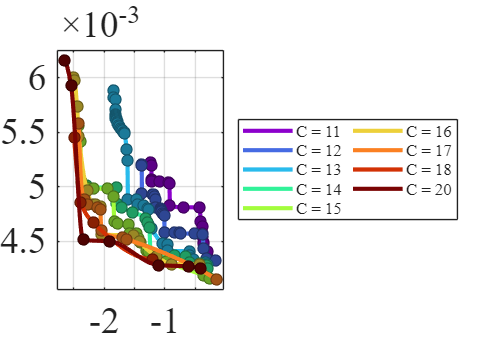


% plot_fitted_surface(result_final.fval)
plot_pareto_smooth(result_final.fval)


[~, idx1] = sort(result_final.fval(:,1));
idx1 = idx1(1);
X1 = result_final.x(idx1,:);

[~, idx2] = sort(result_final.fval(:,2));
idx2 = idx2(1);
X2 = result_final.x(15,:);

idx3_1 = find(result_final.fval(:,3)==11);
tmp = result_final.fval(idx3_1,:)

tmp =    -1.0947    0.0050   11.0000
   -0.9192    0.0048   11.0000
   -1.2207    0.0051   11.0000
   -1.2375    0.0052   11.0000
   -0.3053    0.0044   11.0000
   -0.3582    0.0045   11.0000
   -0.3848    0.0046   11.0000
   -0.4308    0.0048   11.0000
   -1.2207    0.0051   11.0000
   -1.2192    0.0051   11.0000
   -1.2207    0.0051   11.0000
   -0.6999    0.0048   11.0000
   -1.2207    0.0051   11.0000
   -1.2207    0.0051   11.0000
   -1.2207    0.0051   11.0000


[~, idx3_2] = sort(tmp(:,1));
idx3 = idx3_1(idx3_2(3));
X3 = result_final.x(idx3,:);



RP_data = Module_Lib();

x=X3;
n = x(1);
module_raw      = x(2:n+1);
install_raw     = x(15:n+14);
align_raw       = x(28:n+27);
sequence_raw    = x(41:n+40);

%% 机器人初始化
LP = LP_generate(n, module_raw, install_raw, align_raw, sequence_raw, RP_data);
SV = SV_generate(LP);

Goal = Goal_init(SV);
Goal.change = [1 0 0];
tar.POS_e = [1 0 0.2]';
tar.ORI_e = cy(pi/2);
Goal.POS_e{1} = tar.POS_e;
Goal.ORI_e{1} = tar.ORI_e;

[SV_goal, flag_goal, q_goal, w_goal] =  SQP_all(LP, SV, Goal);

 flag  = 0, err_k = 6.93438e-06, w_k = 1.22072


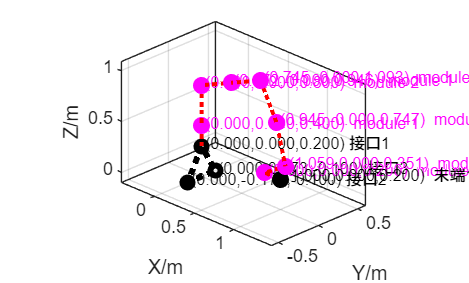

PlotSV(LP,SV_goal);
view([45 25]);
box on

sig_goal = calc_sig_worst_all(SV_goal, LP);

%% 求优化目标3：机器人原始模块数+展开后模块数
num_goal = LP.num_goal;


P_final = result.fval;
plot_fitted_surface(P_final);